# **Euler Angles**

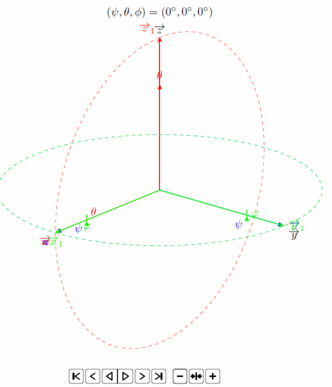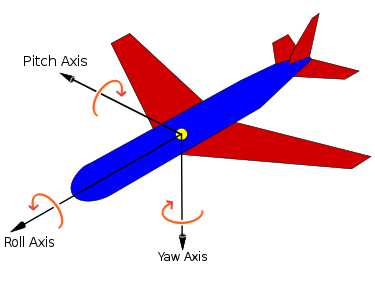

**This live script walks through **[Euler Angles](https://en.wikipedia.org/wiki/Euler_angles)** and how they are used to transform one vector (or in this case a basis) to another vector in **$\Re^3$

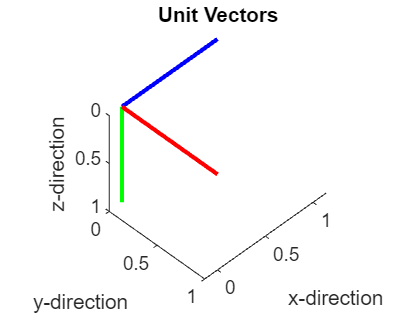

% Define a set of unit vectors
x = [0,1; 0,0; 0,0];
y = [0,0; 0,1; 0,0];
z = [0,0; 0,0; 0,1];

figure(1)
clf 
hold on
axis equal

set(gca,'ydir', 'reverse')
set(gca,'zdir', 'reverse')

plot3(x(1,:), x(2,:), x(3,:),'LineWidth',2, 'Color','blue')
plot3(y(1,:), y(2,:), y(3,:),'LineWidth',2, 'Color','red')
plot3(z(1,:), z(2,:), z(3,:),'LineWidth',2, 'Color','green')

xlabel('x-direction')
ylabel('y-direction')
zlabel('z-direction')
title('Unit Vectors')

view([-45 45])

## Yaw

- Rotation about the z-axis ($\left.z_1 =z_0 \right)$

- Anticlockwise rotation

Yaw: $\left\lbrack \begin{array}{c}
x_1 \\
y_1 \\
z_1 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{ccc}
\cos \left(\psi \right) & -\sin \left(\psi \right) & 0\\
\sin \left(\psi \right) & \cos \left(\psi \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x_0 \\
y_0 \\
z_0 
\end{array}\right\rbrack$

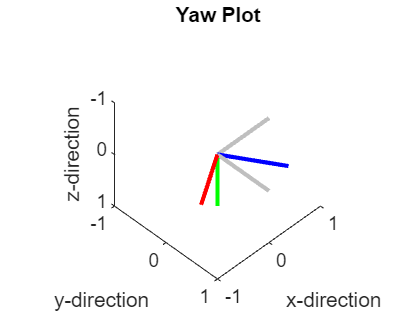

psi =58;

yaw = [cosd(psi), -sind(psi), 0; sind(psi), cosd(psi), 0; 0,0,1];
x1 = yaw*x;
y1 = yaw*y;
z1 = yaw*z;

figure(2)
clf 
hold on
axis equal

xlim([-1 1])
ylim([-1 1])
zlim([-1 1])

set(gca,'ydir', 'reverse')
set(gca,'zdir', 'reverse')

plot3(x(1,:), x(2,:), x(3,:),'LineWidth',2, 'Color','#BFBFBF')
plot3(y(1,:), y(2,:), y(3,:),'LineWidth',2, 'Color','#BFBFBF')
plot3(z(1,:), z(2,:), z(3,:),'LineWidth',2, 'Color','#BFBFBF')

plot3(x1(1,:), x1(2,:), x1(3,:),'LineWidth',2, 'Color','blue')
plot3(y1(1,:), y1(2,:), y1(3,:),'LineWidth',2, 'Color','red')
plot3(z1(1,:), z1(2,:), z1(3,:),'LineWidth',2, 'Color','green')

xlabel('x-direction')
ylabel('y-direction')
zlabel('z-direction')
title('Yaw Plot')

view([-45 45])

## Pitch

- Rotation about the y-axis ($\left.y_1 =y_0 \right)$

- Anticlockwise rotation

Pitch: $\left\lbrack \begin{array}{c}
x_2 \\
y_2 \\
z_2 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{ccc}
\cos \left(\theta \right) & 0 & \sin \left(\theta \right)\\
0 & 1 & 0\\
-\sin \left(\theta \right) & 0 & \cos \left(\theta \right)
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x_1 \\
y_1 \\
z_1 
\end{array}\right\rbrack$

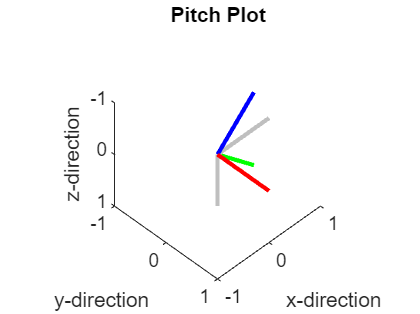

theta =45;

pitch = [cosd(theta), 0, sind(theta); 0,1,0; -sind(theta), 0, cosd(theta)];
x1 = pitch*x;
y1 = pitch*y;
z1 = pitch*z;

figure(3)
clf 
hold on
axis equal

xlim([-1 1])
ylim([-1 1])
zlim([-1 1])

set(gca,'ydir', 'reverse')
set(gca,'zdir', 'reverse')

plot3(x(1,:), x(2,:), x(3,:),'LineWidth',2, 'Color','#BFBFBF')
plot3(y(1,:), y(2,:), y(3,:),'LineWidth',2, 'Color','#BFBFBF')
plot3(z(1,:), z(2,:), z(3,:),'LineWidth',2, 'Color','#BFBFBF')

plot3(x1(1,:), x1(2,:), x1(3,:),'LineWidth',2, 'Color','blue')
plot3(y1(1,:), y1(2,:), y1(3,:),'LineWidth',2, 'Color','red')
plot3(z1(1,:), z1(2,:), z1(3,:),'LineWidth',2, 'Color','green')

xlabel('x-direction')
ylabel('y-direction')
zlabel('z-direction')
title('Pitch Plot')

view([-45 45])

## Roll

- Rotation about the x-axis ($\left.x_1 =x_0 \right)$

- Anticlockwise rotation

Roll: $\left\lbrack \begin{array}{c}
x_3 \\
y_3 \\
z_3 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \left(\phi \right) & -\sin \left(\phi \right)\\
0 & \sin \left(\phi \right) & \cos \left(\phi \right)
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x_2 \\
y_2 \\
z_2 
\end{array}\right\rbrack$

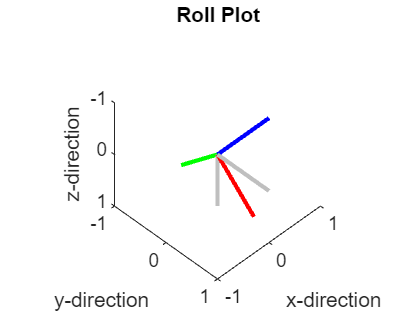

phi =45;
roll = [1,0,0; 0, cosd(phi), -sind(phi); 0, sind(phi), cosd(phi)];
x1 = roll*x;
y1 = roll*y;
z1 = roll*z;

figure(4)
clf 
hold on
axis equal

xlim([-1 1])
ylim([-1 1])
zlim([-1 1])

set(gca,'ydir', 'reverse')
set(gca,'zdir', 'reverse')

plot3(x(1,:), x(2,:), x(3,:),'LineWidth',2, 'Color','#BFBFBF')
plot3(y(1,:), y(2,:), y(3,:),'LineWidth',2, 'Color','#BFBFBF')
plot3(z(1,:), z(2,:), z(3,:),'LineWidth',2, 'Color','#BFBFBF')

plot3(x1(1,:), x1(2,:), x1(3,:),'LineWidth',2, 'Color','blue')
plot3(y1(1,:), y1(2,:), y1(3,:),'LineWidth',2, 'Color','red')
plot3(z1(1,:), z1(2,:), z1(3,:),'LineWidth',2, 'Color','green')

xlabel('x-direction')
ylabel('y-direction')
zlabel('z-direction')
title('Roll Plot')

view([-45 45])

## **Compiled Rotations**

$\left\lbrack \begin{array}{c}
x_f \\
y_f \\
z_f 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{ccc}
\cos \left(\psi \right) & -\sin \left(\psi \right) & 0\\
\sin \left(\psi \right) & \cos \left(\psi \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$\left\lbrack \begin{array}{ccc}
\cos \left(\theta \right) & 0 & \sin \left(\theta \right)\\
0 & 1 & 0\\
-\sin \left(\theta \right) & 0 & \cos \left(\theta \right)
\end{array}\right\rbrack$$\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \left(\phi \right) & -\sin \left(\phi \right)\\
0 & \sin \left(\phi \right) & \cos \left(\phi \right)
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x_0 \\
y_0 \\
z_0 
\end{array}\right\rbrack$

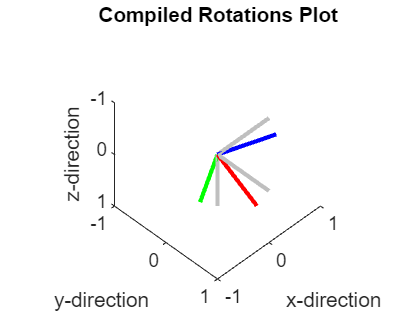

psi = 10;
theta = 10;
phi =10;
yaw = [cosd(psi), -sind(psi), 0; sind(psi), cosd(psi), 0; 0,0,1];
pitch = [cosd(theta), 0, -sind(theta); 0,1,0; sind(theta), 0, cosd(theta)];
roll = [1,0,0; 0, cosd(phi), -sind(phi); 0, sind(phi), cosd(phi)];

cosine_matrix = yaw*pitch*roll;

x1 = cosine_matrix*x;
y1 = cosine_matrix*y;
z1 = cosine_matrix*z;


figure(5)
clf 
hold on
axis equal

a = 1;
xlim([-a a])
ylim([-a a])
zlim([-a a])

set(gca,'ydir', 'reverse')
set(gca,'zdir', 'reverse')

plot3(x(1,:), x(2,:), x(3,:),'LineWidth',2, 'Color','#BFBFBF')
plot3(y(1,:), y(2,:), y(3,:),'LineWidth',2, 'Color','#BFBFBF')
plot3(z(1,:), z(2,:), z(3,:),'LineWidth',2, 'Color','#BFBFBF')

plot3(x1(1,:), x1(2,:), x1(3,:),'LineWidth',2, 'Color','blue')
plot3(y1(1,:), y1(2,:), y1(3,:),'LineWidth',2, 'Color','red')
plot3(z1(1,:), z1(2,:), z1(3,:),'LineWidth',2, 'Color','green')

xlabel('x-direction')
ylabel('y-direction')
zlabel('z-direction')
title('Compiled Rotations Plot')

view([-45 45])